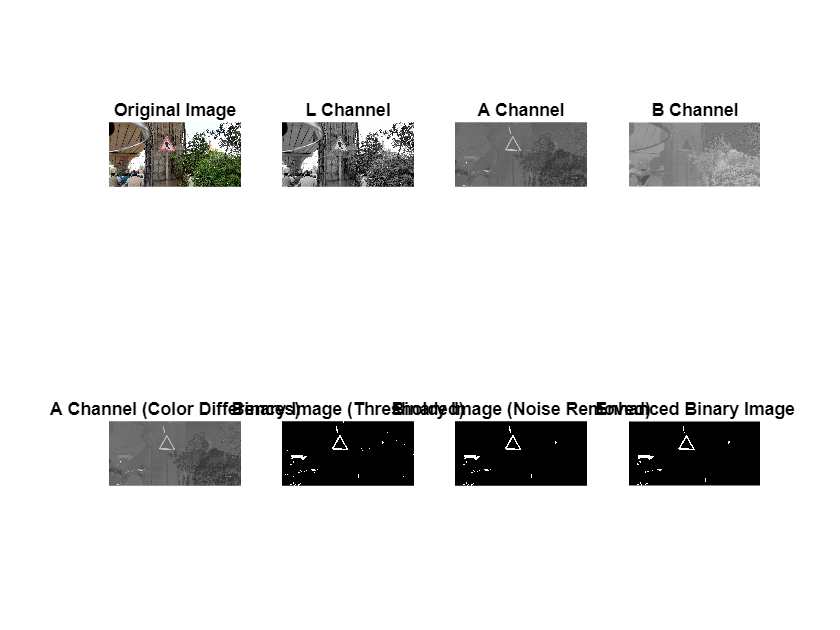

% Ask user to select an image
[filename, filepath] = uigetfile({'*.jpg;*.png', 'Image files (*.jpg, *.png)'}, 'Select an image');
if isequal(filename, 0) || isequal(filepath, 0)
    disp('No image selected. Exiting.');
    return;
end

% Read the selected image
imagePath = fullfile(filepath, filename);
inputImage = imread(imagePath);

% Create a figure to display the images at each stage
figure;

% Display the original image
subplot(2, 4, 1);
imshow(inputImage);
title('Original Image');

% Convert the image to the LAB color space
labImage = rgb2lab(inputImage);

% Display the LAB color space channels
subplot(2, 4, 2);
imshow(labImage(:, :, 1), []);
title('L Channel');
subplot(2, 4, 3);
imshow(labImage(:, :, 2), []);
title('A Channel');
subplot(2, 4, 4);
imshow(labImage(:, :, 3), []);
title('B Channel');

% Extract the "a" channel which represents color differences
aChannel = labImage(:, :, 2);

% Display the "a" channel
subplot(2, 4, 5);
imshow(aChannel, []);
title('A Channel (Color Differences)');

% Thresholding to segment potential traffic sign regions
binaryImage = aChannel > 10; % Adjust threshold as needed

% Display the binary image after thresholding
subplot(2, 4, 6);
imshow(binaryImage);
title('Binary Image (Thresholded)');

% Remove small noise regions
binaryImage = bwareaopen(binaryImage, 200);

% Display the binary image after noise removal
subplot(2, 4, 7);
imshow(binaryImage);
title('Binary Image (Noise Removed)');

% Perform morphological operations to enhance the regions
se = strel('disk', 5);
binaryImage = imclose(binaryImage, se);

% Display the binary image after morphological operations
subplot(2, 4, 8);
imshow(binaryImage);
title('Enhanced Binary Image');

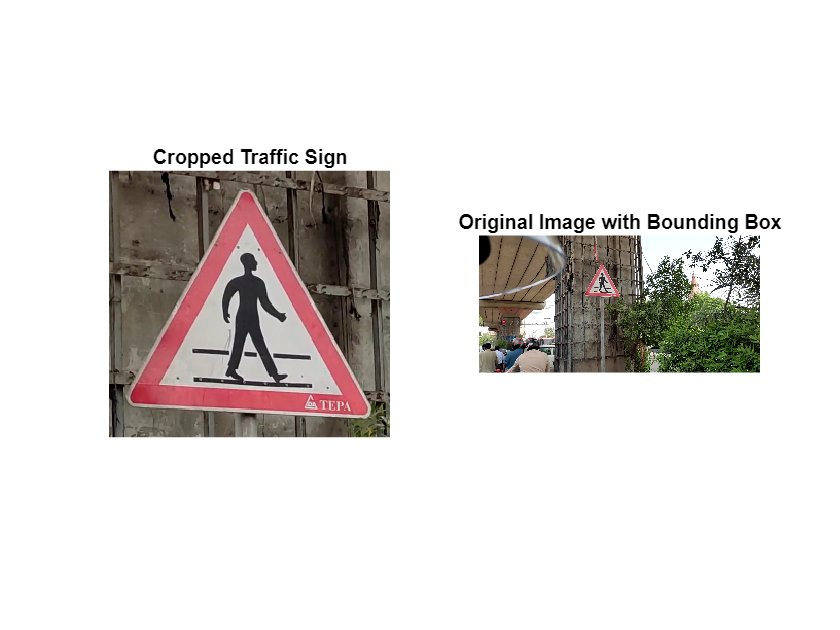


% Identify and label connected components
cc = bwconncomp(binaryImage);
labeledImage = labelmatrix(cc);

% Calculate the area of each connected component
area = regionprops(cc, 'Area');
areaArray = [area.Area];

% Find the largest connected component (assumed to be the traffic sign)
[~, idx] = max(areaArray);

% Create a mask of the detected traffic sign
trafficSignMask = labeledImage == idx;

% Get the bounding box of the detected traffic sign
boundingBox = regionprops(trafficSignMask, 'BoundingBox');
bb = boundingBox.BoundingBox;

% Add a margin around the bounding box
margin = 20; % Adjust the margin size as needed
expandedBoundingBox = [bb(1) - margin, bb(2) - margin, bb(3) + 2*margin, bb(4) + 2*margin];

% Crop the original image using the expanded bounding box
croppedTrafficSign = imcrop(inputImage, expandedBoundingBox);

% Display the cropped traffic sign
figure;
subplot(1, 2, 1);
imshow(croppedTrafficSign);
title('Cropped Traffic Sign');

% Draw the bounding box on the original image
imageWithBoundingBox = insertShape(inputImage, 'Rectangle', bb, 'LineWidth', 2, 'Color', 'red');

% Display the original image with bounding box
subplot(1, 2, 2);
imshow(imageWithBoundingBox);
title('Original Image with Bounding Box');


% Save the cropped traffic sign
outputPath = fullfile(filepath, 'cropped_traffic_sign.png');
% imwrite(croppedTrafficSign, outputPath);
% disp(['Cropped traffic sign saved at: ' outputPath]);
